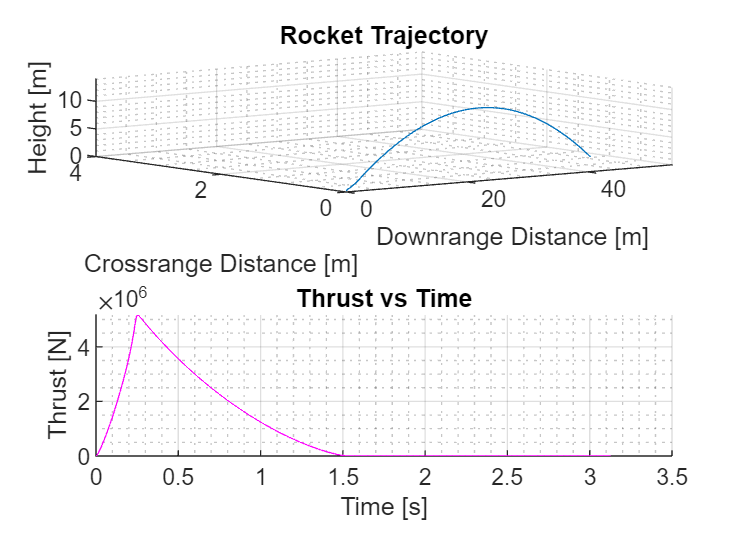

% Jared Steffen
% SID: 104654948
% ASEN 2804
% Date Created: 11/07/2021
% Date Last Modified:

% PURPOSE:

% Given a set of initial conditions, use ode45 to show the
% trajectory and the Thrust vs Time of a bottle rocket.

% FUNCTION INPUTS/OUTPUTS:

% Main:
% initial conditions, timespan, ode45 call, plot_phase_flight call, display
% max height and distance

% getConst():
% saves constant values and is used to call them in later functions
 
% flight_phase:
% Inputs: time and a related current state vector 
% Outputs: time and a related current state vector w/ rates of change

% plot_flight_phase:
% Inputs: time and related current state vector
% Outputs: Height vs Distance and Thrust vs Time graphs

% ASSUMPTIONS:

% Ambient air pressure remains constant at all elevations.

%----------------------------------------------------------------------------------------

% House Cleaning
clc
close all

% Constants call
const = getConst();

% Initial Conditions
ICs = [const.x0 const.y0 const.z0 const.vx const.vy const.vz const.m_Rocket_Initial ...
    const.m_Air_Initial const.Vol_Air_Initial];

% Time span
tspan = (0:0.001:5); % [s]

% ode45 call
[t, state_vector] = ode45(@flight_phase, tspan, ICs);

% plot3(state_vector(:,1),state_vector(:,2),state_vector(:,3))
% grid on; grid minor
% title('Rocket Trajectory')
% xlabel('Downrange Distance')
% ylabel('Crossrange Distance')
% zlim([0 30])
% zlabel('Vertical Distance')

% Graph Results
plot_flight_phase(t,state_vector);

stop_plot = find(state_vector(:,3) < 0);
x = state_vector(1:stop_plot-1,1);
y = state_vector(1:stop_plot-1,2);
z = state_vector(1:stop_plot-1,3);

% Display Max Height/Distance
str1 = ['The Maximum Actual Downrange Distance is: ',num2str(max(x)),' meters.'];
str2 = ['The Maximum Actual Crossrange Distance is: ',num2str(max(y)),' meters.'];
str3 = ['The Maximum Actual Height is: ',num2str(max(z)),' meters.'];
disp(str1)

The Maximum Actual Downrange Distance is: 51.2995 meters.


disp(str2)

The Maximum Actual Crossrange Distance is: 1.0427 meters.


disp(str3)

The Maximum Actual Height is: 11.233 meters.
